# **Controller Design for DC Motor Speed Control using Frequency Response**

**Name: _ _ _ _ _ _ _ _ _ _ _ **

**H-ID: _ _ _ _ _ _ _ _ _ _ _ _ **

The dynamic equations in the Laplace domain and the open-loop transfer function of the DC Motor are the following.


$$s(Js +b) \theta(s) = KI(s)$$



$$(Ls + R)I(s) = V(s) - Ks\theta(s)$$



$$P(s) = \frac{\dot{\theta}(s)}{V(s)} = \frac{K}{(Js +b)(Ls+R) + K^2}$$


The structure of the control system has the form shown in the figure below.

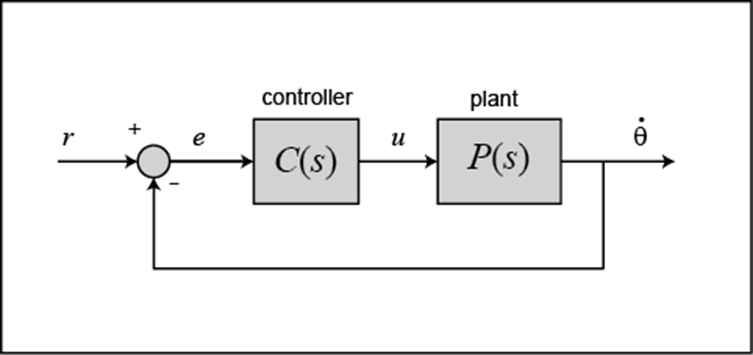

The physical parameters for our example are:

`(J)`     `moment of inertia of the rotor`     `0.01 kg.m^2`

`(b)`     `motor viscous friction constant`    `0.1 N.m.s`

`(Ke)`    `electromotive force constant`       `0.01 V/rad/sec`

`(Kt)`    `motor torque constant`              `0.01 N.m/Amp`

`(R)`     `electric resistance`                `1 Ohm`

`(L)`     `electric inductance`                `0.5 H`

clc;
clear;

% Define the input parameters
J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;

kp = 0;
ki = 0;
kd = 0;

## Design Characteristics

Design a controller using frequency response method have following design criteria for a 1rad/sec.

- Settling time less than 2 seconds

- Overshoot less than 5%

- Steady-state error less than 1%

 Create the open loop transfer function

s = tf('s');    
% define the transfer function below and save it in 'P_motor'


%  get the close loop transfer function (sys_cl) and its step response


grid on

% transient characteriatics of close loop sys



## Frequency Reponse of the system

Generate the bode plot for the open loop system

Note:

[`bode(sys)`](https://www.mathworks.com/help/releases/R2020a/control/ref/bode.html) creates a Bode plot of the frequency response of a dynamic system model `sys`. The plot displays the magnitude (in dB) and phase (in degrees) of the system response as a function of frequency. `bode` automatically determines frequencies to plot based on system dynamics.

[`margin(sys)`](https://www.mathworks.com/help/releases/R2023a/control/ref/dynamicsystem.margin.html) plots the Bode response of `sys` on the screen and indicates the gain and phase margins on the plot. Gain margins are expressed in dB on the plot.

f1 = figure;
set(gcf,'Visible','on')

% Generate the Bode Plot of the plant - P_motor


% indicates the gain and phase margins on the same plot
hold on;


% Switch on the grid
grid on;

% add the title of the plot
%title("Frequency Response DC Motor Speed")

hold off;

## Controller Design

Suppose the suitable Pm and estimate the frequency

- Gain crossover frequency  = ?

- phase margin for a gain crossover frequency = ?

- magnitude at this frequency = ?

Note:

`[mag,phase,wout] =` `bode``(sys)` returns the magnitude and phase of the response at each frequency in the vector `wout`. The function automatically determines frequencies in `wout` based on system dynamics. This syntax does not draw a plot.

*lets suppose our phase margin is 60 deg*

% Bode Diagram with Gm & Pm
[mag,phase,wout] = bode(P_motor,10)

% Get the magnitude (mag) and phase angle (phase) at required frequency w
mag_dB = 20*log10(mag)

% Define kp with required gain value
kp = 1/mag

grid on;

### Proportional Controller

Add a proportional controller with required gain and get the Pm and Gm

- Required Proportional gain = ?

% Create a PID controller with only Proportional gain
C = pid(kp, ki, kd)

% generate the bode plot of controller


% generate the bode plot of compensated Plant


% indicates the gain and phase margins on the same plot


grid on;
hold off;

### Close Loop Step Response

Analyse the Close Loop Step response with Proportional controller

f2 = figure;
set(gcf,'Visible','on')

% generate the transfer function & step response of compensated close loop sys with controller


% transient characteriatics of compensated close loop sys



System Characteristics:

- Overshoot = ?

- Settling Time = ?

- Steady-state value = ?

Does the system achieved the given design criteria?

If No, what else is required to improve in the response?

- .......

### PID Controller

Adding Integral and Derivative controller

$K_i$ = 200

$K_d$ = 10

ki = 200;
kd = 10;
% Define kd & ki with the given gain values


f3 = figure;
set(gcf,'Visible','on')

% generate the transfer function & step response of compensated close loop sys with controller



% transient characteriatics of compensated close loop sys


Analyse the Bode Plot and comment:

- .......

### Close Loop Step Response with PID Controller

Analyse the Close Loop Step response with Proportional controller

% generate the step response of close loop sys with controller



% transient characteriatics of close loop sys




System Characteristics:

- Overshoot = ?

- Settling Time = ?

- Steady-state value = ?

Does the system achieved the given design criteria? Comment.

.......